rng(13);
n=300;
rand1 = exprnd(0.2,[1,floor(n/3)]);
rand3 = exprnd(0.2,[1,floor(n/3)]);
rand4 = exprnd(0.2,[1,floor(n/3)]);

y = ([rand1,rand3,rand4])

y =     0.0503    0.2875    0.0386    0.0070    0.0056    0.1582    0.0992    0.0508    0.0888    0.0651    0.6703    0.2418    0.5677    0.0308    0.1973    0.0772    0.2723    0.2114    0.9331    0.2053    0.0104    0.3047    0.2283    0.0172    0.6890    0.5464    0.0925    0.0270    0.9485    0.0585    0.0414    0.5161    0.0842    0.1350    0.1468    0.0091    2.2656    0.2797    0.0679    0.2250    0.2568    0.0726    0.0170    0.2817    0.1561    0.2749    0.1939    0.1007    0.0517    0.5379


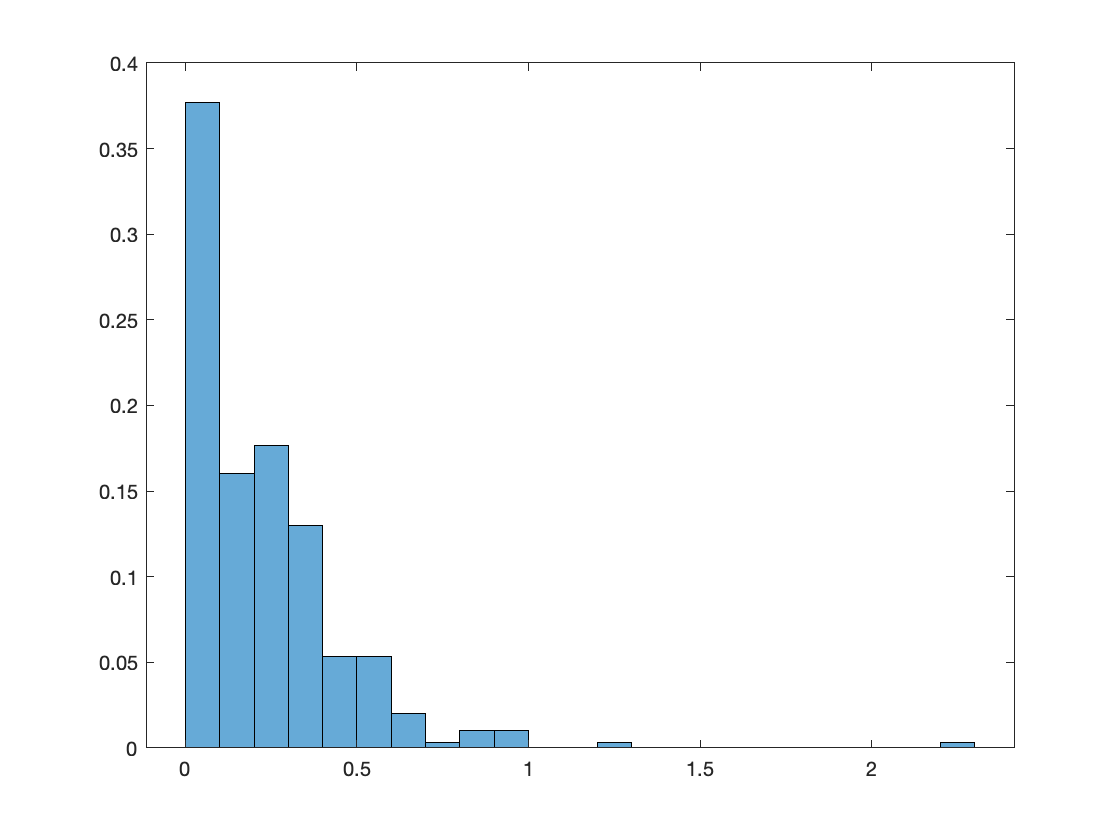

% [f,yi] = ksdensity(y);
% plot(yi,f)
% title('density')
% plot(yi,log(f))
% title('log density')
histogram(y, 'Normalization','probability')


sum(y<0)

ans = 0

sum(y>1)

ans = 2


knots = [0.0, 0.1, 0.21, 0.41, 0.6, 0.81, 1];
d = 5;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=1;
solve_this = @(a) (constraintFunc(a));
initial = [6, 4, 3, 1, 0.5];
initial_guess = fsolve(solve_this, initial.*0.1, options)

initial_guess =     0.3988    0.1255   -0.0066   -0.1678   -0.1999



num_iters = 50000;
burn_in = 1000;
proposal_scale = 1e-3

proposal_scale = 1.0000e-03


ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc)

Finished 1000 iterations.
Current value: 4.233927e-01 2.753636e-01 8.919405e-02 -3.467147e-01 -3.359738e-01.
Finished 2000 iterations.
Current value: 4.336228e-01 2.613793e-01 1.277242e-01 -3.500994e-01 -3.779416e-01.
Finished 3000 iterations.
Current value: 4.514078e-01 2.342527e-01 1.406628e-01 -3.680292e-01 -3.593263e-01.
Finished 4000 iterations.
Current value: 4.514078e-01 2.342527e-01 1.406628e-01 -3.680292e-01 -3.593263e-01.
Finished 5000 iterations.
Current value: 4.486220e-01 2.429312e-01 1.385251e-01 -3.657040e-01 -3.674687e-01.
Finished 6000 iterations.
Current value: 4.486220e-01 2.429312e-01 1.385251e-01 -3.657040e-01 -3.674687e-01.
Finished 7000 iterations.
Current value: 4.486220e-01 2.429312e-01 1.385251e-01 -3.657040e-01 -3.674687e-01.
Finished 8000 iterations.
Current value: 4.486220e-01 2.429312e-01 1.385251e-01 -3.657040e-01 -3.674687e-01.
Finished 9000 iterations.
Current value: 4.486220e-01 2.429312e-01 1.385251e-01 -3.657040e-01 -3.674687e-01.
Finished 10000 iter

samples =     0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234    0.4234
    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.2754    0.275

accepts =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


mean(accepts)

ans = 6.1223e-05

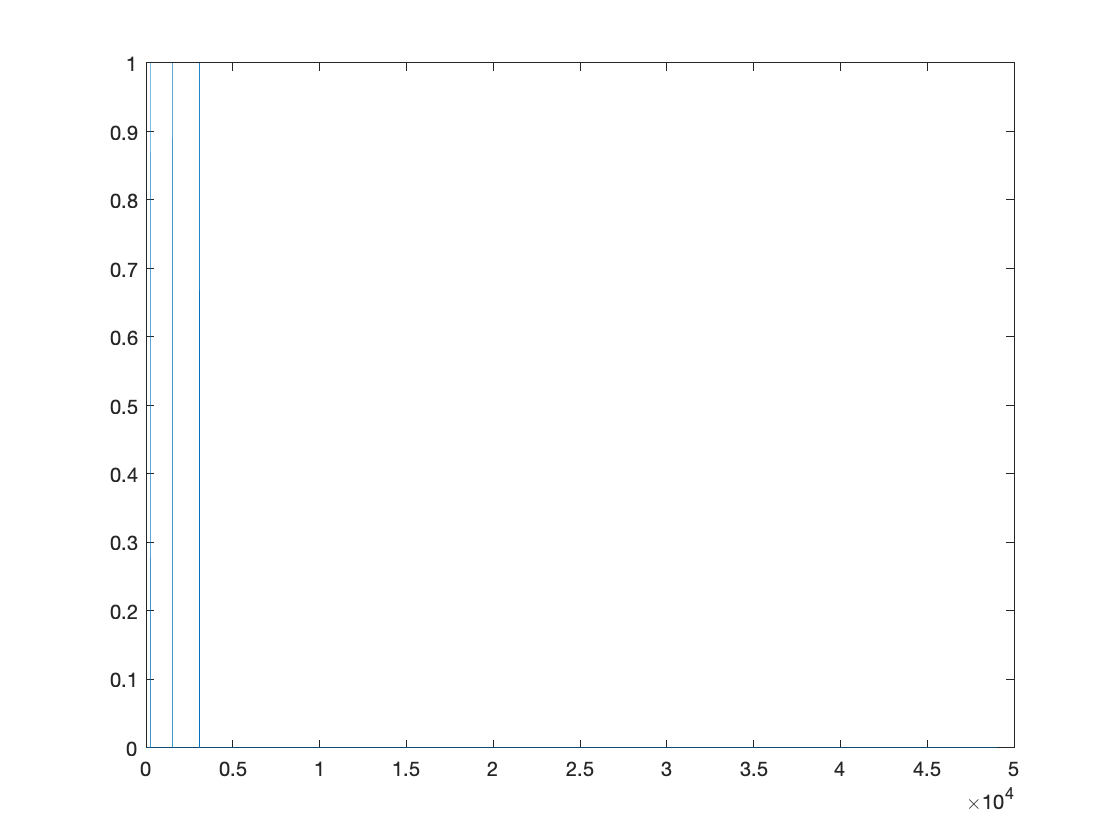

save("MH_logsplineDraws.mat",'samples');

plot(accepts)

% I will need to get a point estimator at some point, but for now let's
% just choose a theta and see if I can plot it.
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,min_index)

chosen_theta =     0.4486
    0.2429
    0.1385
   -0.3657
   -0.3675


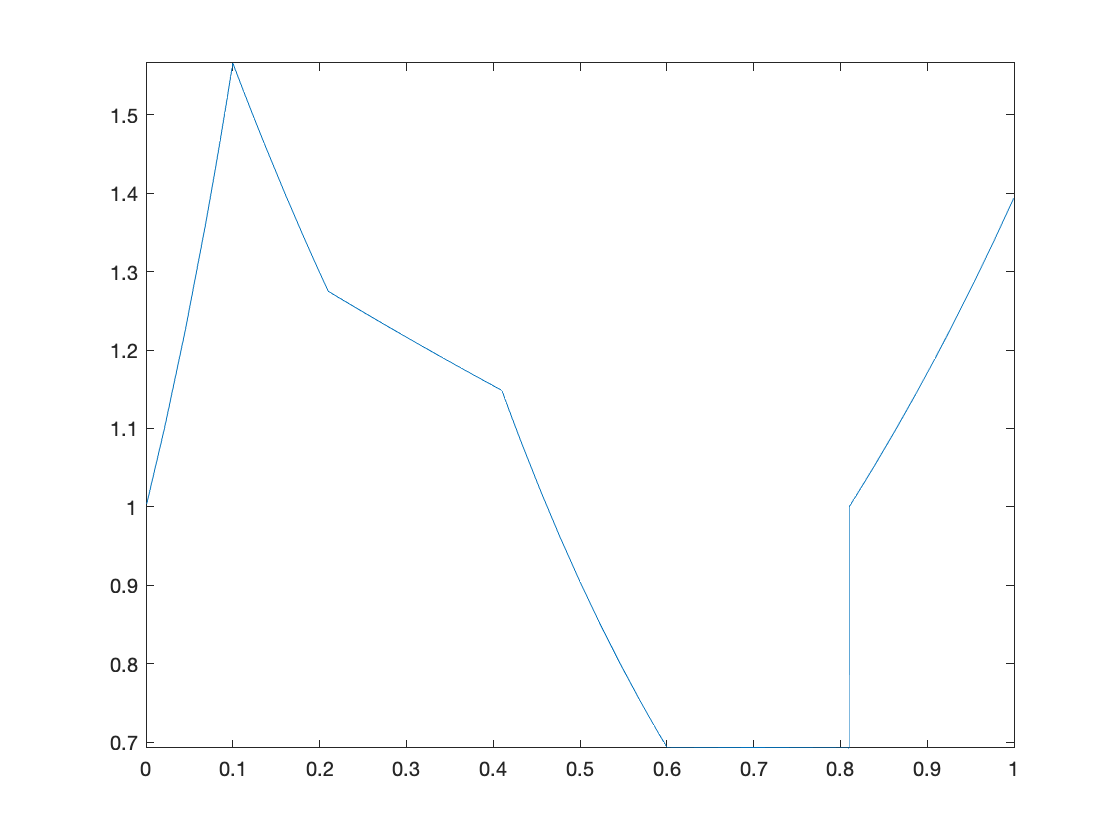


syms func(x)
func(x) = piecewise( (knots(1) < x)&(x <= knots(2)),exp(chosen_theta(1)*(x-knots(1))/(knots(2)-knots(1))), ...
                               (knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                               (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                               (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                               (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                               (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(5)*(knots(6)-x)/(knots(6)-knots(5))));

% fplot(y, [0,1])
fplot(func, [0,1])


double(int(func, 0, 1))

ans = 1.0664